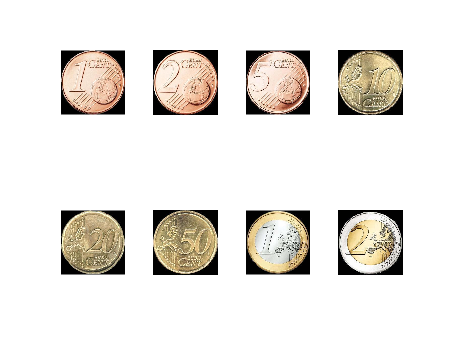

% Mehr Daten generieren
iterations = 1000;
for i = 1:8
    path = generateTestData(i-1, iterations);
    subplot(2,4,i);
    imshow(imread(path));
end

% Laden und Labeln
datasetPath = 'Dataset/';
imds = imageDatastore(datasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Unterteilen in Trainings- und Validierungsdaten
numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, 'randomized');

% Netzwerkarchitektur definieren
inputSize = [256 256 3];
numClasses = 8;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


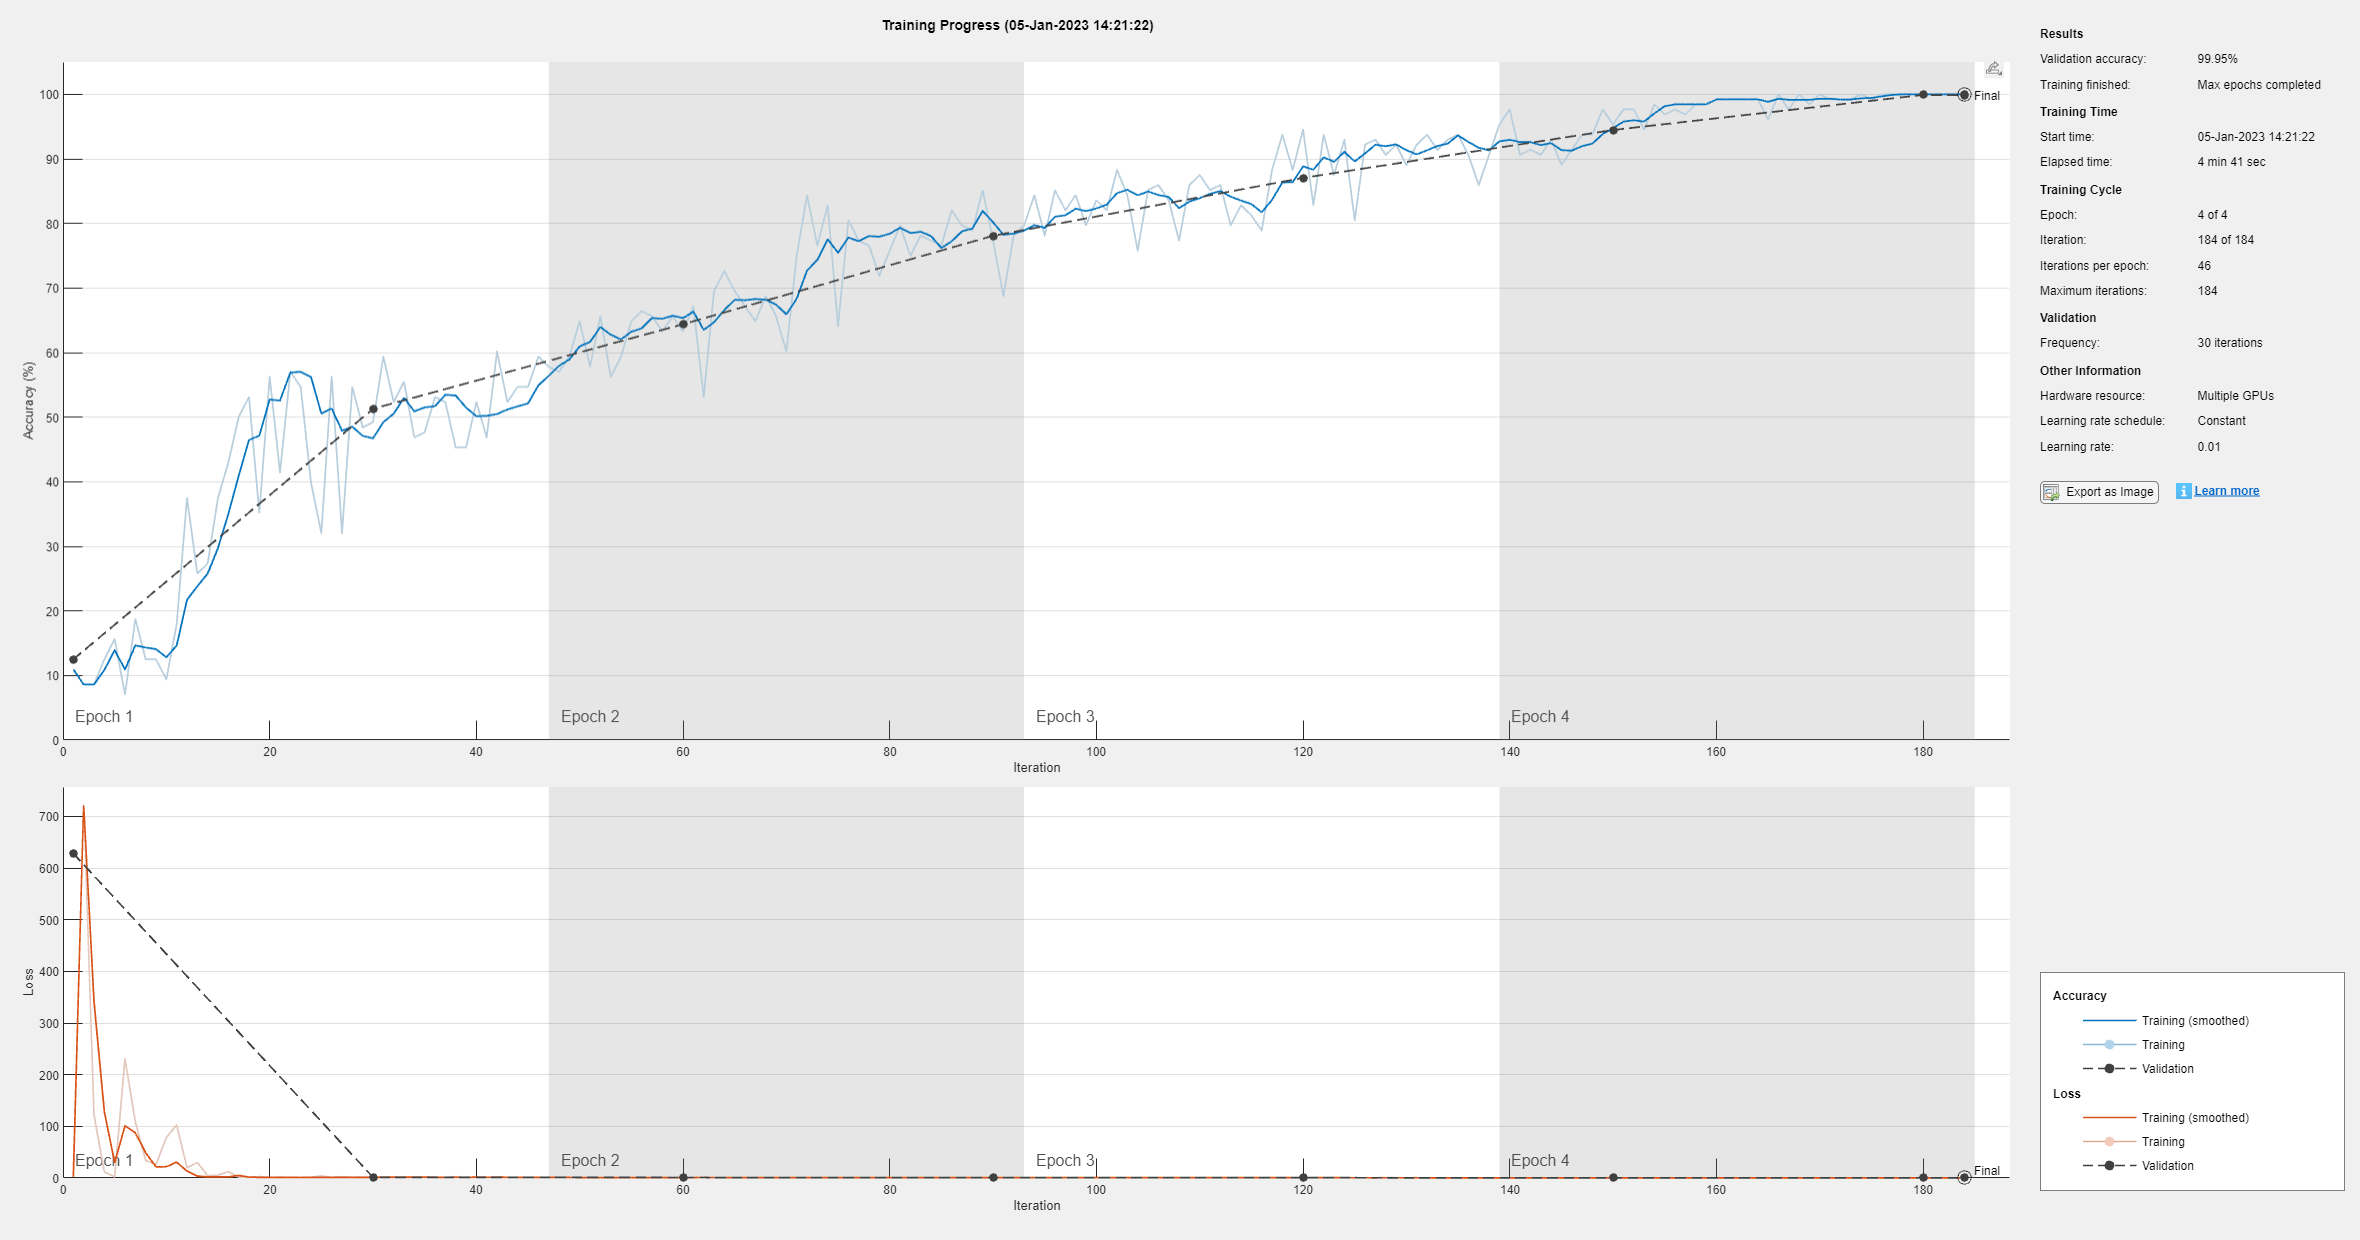

% Netzwerk trainieren
options = trainingOptions('sgdm', 'MaxEpochs', 4,'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, 'Verbose', false, 'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'parallel');

net = trainNetwork(imdsTrain, layers, options);

serializedNet = net;
save serializedNet;

% Netzwerk laden
load serializedNet
net = serializedNet;

% Netzwerk testen
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9995


serializedNet = net;
save serializedNet;

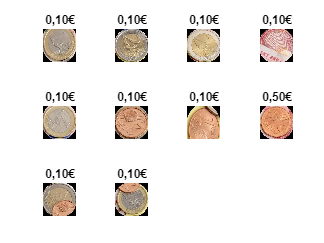

% Input-Bilder abgleichen
imdsTest = imageDatastore(fullfile('readCoins'), IncludeSubfolders=true);
%imdsTest = imdsValidation;
YTest = classify(net, imdsTest);

numImages = 10; %12
idx = randperm(numel(imdsTest.Files), numImages);
tiledlayout('flow')
total = 0;
for i=1:numImages
    nexttile
    imshow(imdsTest.Files{idx(i)});
    title(label2name(YTest(idx(i))))
    total = total + label2decimal(YTest(idx(i)));
end


display(strcat('Total:', sprintf('%0.2f', total), '€'));

Total:1.40€


function origPath = generateTestData(index, iterations)
    rng(0, 'twister');
    path = sprintf('Dataset/%01d/', index);
    origPath = strcat(path, 'orig.jpg');
    I = imresize(imread(origPath), [256 256]);
    imwrite(I, origPath, 'jpg');

    for i = 1:iterations
        angle = randi([0, 359],1,1);
        In = imrotate(I, angle);
        
        targetSize = [256 256];
        win = centerCropWindow2d(size(In), targetSize);
        In = imcrop(In, win);

        str = fullfile(path,  sprintf('generatedData_%03d.jpg', i));
        imwrite(In, str, 'jpg');
    end
end

function res = label2name(label)
    switch (string(label))
        case '0'
            res = '0,01€';
        case '1'
            res = '0,02€';
        case '2'
            res = '0,05€';
        case '3'
            res = '0,10€';
        case '4'
            res = '0,20€';
        case '5'
            res = '0,50€';
        case '6'
            res = '1,00€';
        case '7'
            res = '2,00€';
    end
end

function res = label2decimal(label)
    switch (string(label))
        case '0'
            res = 0.01;
        case '1'
            res = 0.02;
        case '2'
            res = 0.05;
        case '3'
            res = 0.1;
        case '4'
            res = 0.2;
        case '5'
            res = 0.5;
        case '6'
            res = 1;
        case '7'
            res = 2;
    end
end